clear variables
close all

load('Tests\RPC_TT_test\S11_test\SIPI_2layer.mat');
xi_train = xi_train*2-1;
xi_test = xi_test*2-1;


m = 6;

tic
S11_total = pc_collocation_total(xi_train,S11_train,xi_test,m ,'Legendre');
toc

Elapsed time is 0.701792 seconds.


norm(S11_total-S11_test,"fro")/norm(S11_test,"fro")

ans = 0.0428

m = 5;
tic
[S11_total2,n_rpc,d_rpc] = rpc_total(xi_train,S11_train,xi_test,m,'Legendre',0.1,0.01,5e-3);
toc

Elapsed time is 125.820454 seconds.


norm(S11_total2-S11_test,'fro')/norm(S11_test,'fro')

ans = 0.0681

[~,d] = size(xi_train);
m = 5;
N = (m+1)*ones(d,1);
r = 3;

x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [S11_train(1,1); zeros(r-1,1)];

[S11_Newton,PC_coefficients_TT,training_err,test_err,n_iterations] = pc_collocation_tensor_optimization...
    (xi_train,S11_train,x,xi_test,m,'Legendre','TT-Newton',0.4,0.01,5e-3,0.9,r,true);

    0.0031    0.0034    9.0000

    0.0016    0.0017    1.0000

    0.0014    0.0016    1.0000

    0.0013    0.0015    1.0000

    0.0013    0.0015    1.0000

    0.0012    0.0015    1.0000

    0.0012    0.0014    1.0000

    0.0012    0.0014    1.0000

    0.0012    0.0013    1.0000

    0.0011    0.0013    1.0000

    0.0010    0.0012    1.0000

    0.0010    0.0011    1.0000

    0.0009    0.0010    1.0000

    0.0008    0.0010    1.0000

    0.0008    0.0009    1.0000

    0.0007    0.0008    1.0000

    0.0006    0.0007    1.0000

    0.0006    0.0007    1.0000

    0.0005    0.0006    1.0000

    0.0005    0.0006    1.0000

    0.0005    0.0005    1.0000

    0.0004    0.0005    1.0000

    0.0004    0.0005    1.0000

    0.0004    0.0004    1.0000

    0.0004    0.0004    1.0000

    0.0003    0.0004    1.0000

    0.0003    0.0003    1.0000

    0.0003    0.0003    1.0000

    0.0003    0.0003    1.0000

    0.0002    0.0003    1.0000

    0.0002    0.0003    1.0000

    0.00

norm(S11_Newton-S11_test,"fro")/norm(S11_test,"fro")

ans = 0.0403

m = 3;
[~,d] = size(xi_train);
N = (m+1)*ones(d,1);
x = TTrand(N,3);
x = TTorthogonalizeLR(x);
x = TTorthogonalizeRL(x);

tic
[S11_Newton2,N_coefficients,D_coefficients,n_iterations] =...
    rpc_TT(xi_train,S11_train,x,xi_test,m,'Hermite',...
    0.5,0.01,3e-3,0.9,4);

    0.0024    0.0029   67.0000

    0.0024    0.0030   18.0000

    0.0026    0.0030    4.0000

    0.0025    0.0029    3.0000

    0.0025    0.0028    2.0000

    0.0020    0.0023    2.0000

    0.0028    0.0029    1.0000

    0.0024    0.0025    1.0000

    0.0023    0.0023    1.0000

    0.0023    0.0024    1.0000

    0.0024    0.0025    1.0000

    0.0026    0.0026    1.0000

    0.0028    0.0028    1.0000

    0.0029    0.0029    1.0000

    0.0027    0.0029    2.0000

    0.0025    0.0026    1.0000

    0.0024    0.0024    1.0000

    0.0024    0.0023    1.0000

    0.0024    0.0023    1.0000

    0.0024    0.0024    1.0000

    0.0022    0.0023    1.0000

    0.0023    0.0024    1.0000

    0.0023    0.0024    1.0000

    0.0023    0.0024    1.0000

    0.0023    0.0025    1.0000

    0.0023    0.0025    1.0000

    0.0023    0.0025    1.0000

    0.0023    0.0025    1.0000

    0.0023    0.0024    1.0000

    0.0023    0.0023    1.0000

    0.0023    0.0022    1.0000

    0.00

    0.0435    0.0490  100.0000



    0.0440    0.0500  100.0000

    0.0445    0.0510  100.0000

    0.0433    0.0518  100.0000

    0.0436    0.0525  100.0000

    0.0435    0.0530  100.0000

    0.0430    0.0532  100.0000

    0.0428    0.0529   96.0000

    0.0423    0.0516  100.0000

    0.0421    0.0502  100.0000

    0.0425    0.0500   33.0000

    0.0418    0.0499   71.0000

    0.0416    0.0509   26.0000

    0.0415    0.0519   37.0000

    0.0416    0.0532   30.0000

    0.0415    0.0548   79.0000

    0.0422    0.0562   68.0000

    0.0429    0.0577   90.0000

    0.0441    0.0584   76.0000

    0.0449    0.0588   82.0000

    0.0455    0.0589  100.0000

    0.0466    0.0592   78.0000

    0.0472    0.0585  100.0000

    0.0483    0.0591   20.0000

    0.0473    0.0561  100.0000

    0.0456    0.0571  100.0000

    0.0456    0.0586   74.0000

    0.0456    0.0596   29.0000

    0.0457    0.0597   40.0000

    0.0459    0.0593   45.0000

    0.0462    0.0583   52.0000

    0.0467    0.0566   55.0000

    0.04

toc

Elapsed time is 163.358474 seconds.


err1 = norm(S11_Newton2-S11_test,'fro')/norm(S11_test,'fro')

err1 = 0.0348

close all

S11_mean0 = mean(abs(S11_test));
S11_sigma0 = std((S11_test));

% S11_mean1 = mean(abs(S11_Newton2));
% S11_sigma1 = std((S11_Newton2));

S11_mean4 = mean(abs(S11_total));
S11_sigma4 = std((S11_total));

scale = 1e9;
freq = linspace(1000,1e9,334);
f = figure(2);
subplot(2,1,1);
hold on
plot(freq/scale,S11_mean0,'k-','LineWidth',3.5);
plot(freq/scale,S11_mean4,'r--','LineWidth',3);
% plot(freq/scale,S11_mean1,'g--','LineWidth',2);
legend('Monte Carlo simulation','Total order','TT-Newton')

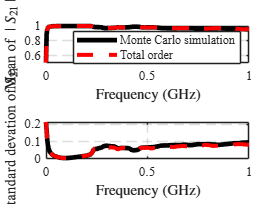

grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid S_{21} \mid $','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',10)
box on;


subplot(2,1,2);
hold on
plot(freq/scale,S11_sigma0,'k-','LineWidth',3.5);
plot(freq/scale,S11_sigma4,'r--','LineWidth',3);
% plot(freq/scale,S11_sigma1,'g--','LineWidth',2);
% ylim([0.0 0.01])
grid on
ylabel('Standard devation of $ S_{21} $','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',10)
box on;

f.Position = [100 100 675 500];

pdf_freq_idx = 200;
f = figure;
histogram(abs(S11_test(:,pdf_freq_idx)),50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N,edges] = histcounts(abs(S11_total(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'r:','LineWidth',2)
% [N,edges] = histcounts(abs(S11_Newton(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'g:','LineWidth',3)

set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
legend('MC','Total order','TT-Newton','interpreter','LaTex');

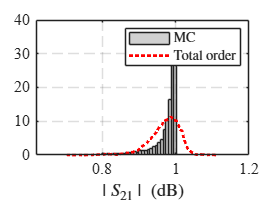

xlabel('$ \mid S_{21} \mid $ (dB)','interpreter','LaTex')
f.Position = [100 100 675 500];